NEWRB, neurons = 0, MSE = 0.0529646
NEWRB, neurons = 4, MSE = 0.0140385


NEWRB, neurons = 8, MSE = 0.0124832


NEWRB, neurons = 12, MSE = 0.00292324


NEWRB, neurons = 16, MSE = 0.00282894


NEWRB, neurons = 20, MSE = 0.00266478


NEWRB, neurons = 24, MSE = 0.00261924


NEWRB, neurons = 28, MSE = 0.00168104


NEWRB, neurons = 32, MSE = 0.00162053


NEWRB, neurons = 36, MSE = 0.00162783


NEWRB, neurons = 40, MSE = 0.0016083


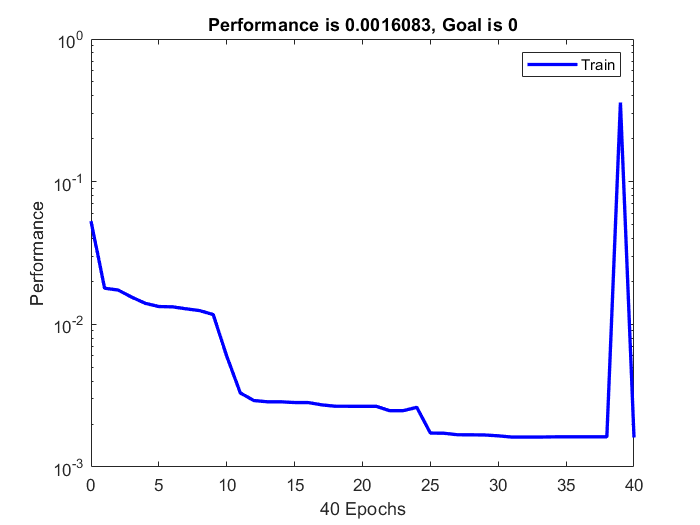

close all, clear  clc, format compact

data = xlsread('C:\Users\tcttn\Desktop\matlab\veri.xlsx');

data = xlsread('C:\Users\tcttn\Desktop\matlab\data2.xlsx');

%D = data(:,end);

data_normalized = normalize(data,'range');
data = data_normalized;
input_train = data(1:40,1:2);
target_train = data(1:40,end);
input_test = data(41:50,1:2);
target_test = data(41:50,end);

P = input_train';
T= target_train';

PT = input_test';
TT = target_test';

% choose a spread constant
spread = 1;
% choose max number of neurons
K = 40;
% performance goal (SSE)
goal = 0;
% number of neurons to add between displays
Ki = 4;
% create a neural network
net = newrb(P,T,goal,spread,K,Ki);



% view network
view(net)

% simulate RBFN on training data
Y = net(P);


YT = sim(net,PT);

YT= (YT*4.06)

YT = 	1.0e+03 *

    0.0005    0.0015    0.0004    0.0006    0.0027    2.1708    0.0011    0.0019    0.0006    0.1953


TT= ((TT*4.06))

TT =     1.1500    2.0000    1.5000    2.1500    2.8000    2.5900    1.5400    2.0000    2.6100    3.0600


mse(net,TT,YT)

ans = 4.7381e+05

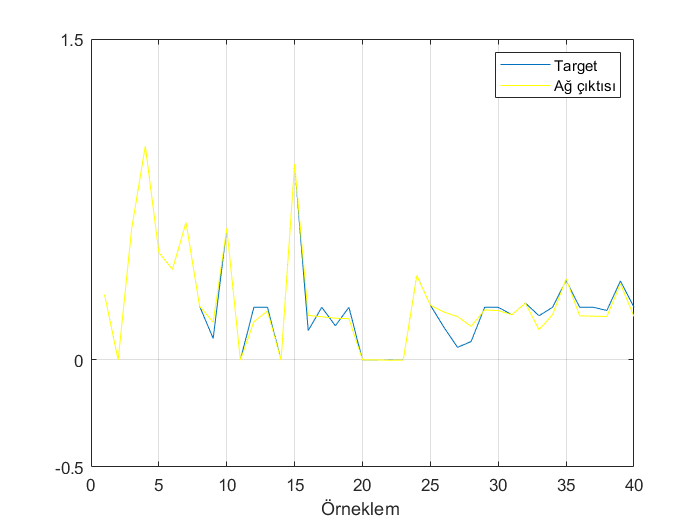



figure;
plot(T')
hold on
grid on
plot(Y','y')
ylim([-0.5 1.5])
set(gca,'ytick',[-0.5 0 1.5])
legend('Target','Ağ çıktısı')
xlabel('Örneklem ')

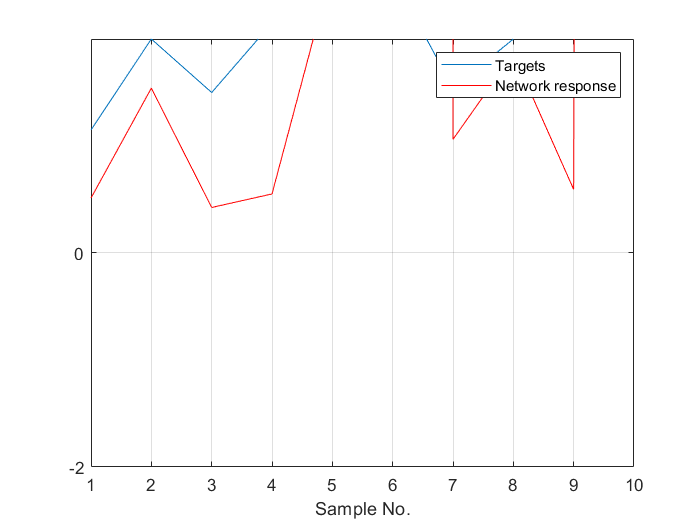


figure;
plot(TT')
hold on
grid on
plot(YT','r')
ylim([-2 2])
set(gca,'ytick',[-2 0 6])
legend('Targets','Network response')
xlabel('Sample No.')